# Pb4

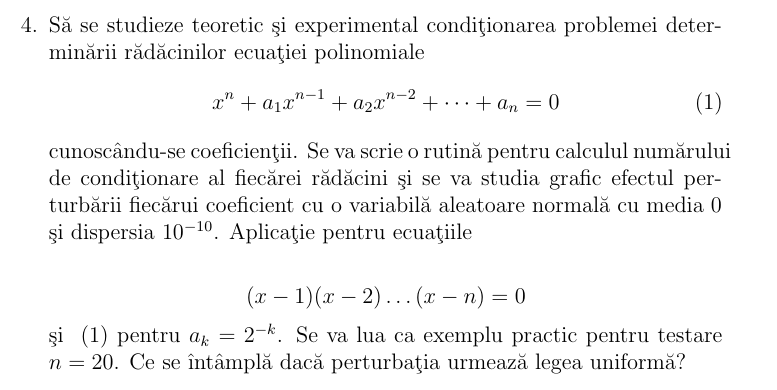

(a):   (x - 1)(x - 2)...(x - 20)

n = 20;

r_a = 1:n ;                     % radacinile exacte
p_a = poly(r_a);                % coeficienții polinomului
roots_a_orig = roots(p_a);      % radacini initiale

% Perturbare normala (N(0, 1e-10))
perturb_a_norm = randn(size(p_a)) * 1e-10;
roots_a_pert_norm = roots(p_a + perturb_a_norm);

% Perturbare uniforma in [-1e-10, 1e-10]
perturb_a_unif = (rand(size(p_a)) - 0.5) * 2 * 1e-10;
roots_a_pert_unif = roots(p_a + perturb_a_unif);


(b):   a_k = 2^(-k)

p_b = [1, 2.^(-(1:n))];
roots_b_orig = roots(p_b);

% Perturbare normala (N(0, 1e-10))
perturb_b_norm = randn(size(p_b)) * 1e-10;
roots_b_pert_norm = roots(p_b + perturb_b_norm);

% Perturbare uniforma in [-1e-10, 1e-10]
perturb_b_unif = (rand(size(p_b)) - 0.5) * 2 * 1e-10;
roots_b_pert_unif = roots(p_b + perturb_b_unif);


Comparare:

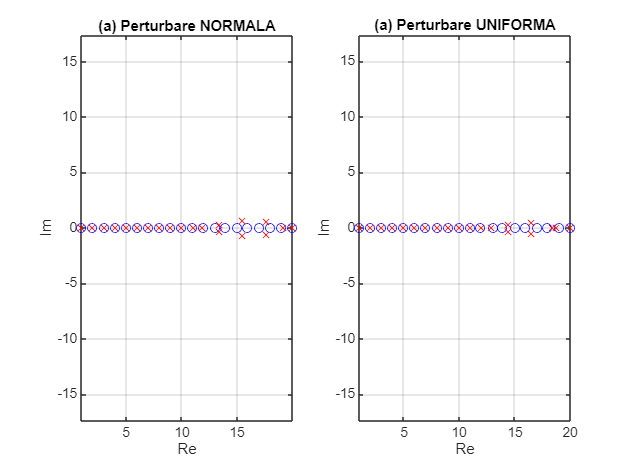

% --- (a) Normal vs Uniform ---
figure;
subplot(1,2,1);
plot(real(roots_a_orig), imag(roots_a_orig), 'bo'); hold on;
plot(real(roots_a_pert_norm), imag(roots_a_pert_norm), 'rx');
title('(a) Perturbare NORMALA'); xlabel('Re'); ylabel('Im'); axis equal; grid on;

subplot(1,2,2);
plot(real(roots_a_orig), imag(roots_a_orig), 'bo'); hold on;
plot(real(roots_a_pert_unif), imag(roots_a_pert_unif), 'rx');
title('(a) Perturbare UNIFORMA'); xlabel('Re'); ylabel('Im'); axis equal; grid on;

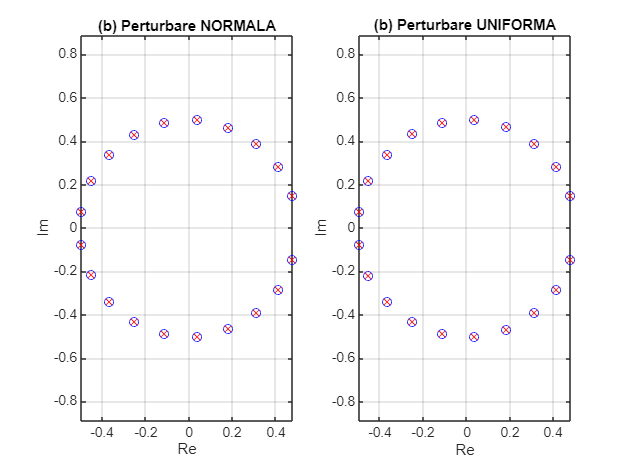


% --- (b) Normal vs Uniform ---
figure;
subplot(1,2,1);
plot(real(roots_b_orig), imag(roots_b_orig), 'bo'); hold on;
plot(real(roots_b_pert_norm), imag(roots_b_pert_norm), 'rx');
title('(b) Perturbare NORMALA'); xlabel('Re'); ylabel('Im'); axis equal; grid on;

subplot(1,2,2);
plot(real(roots_b_orig), imag(roots_b_orig), 'bo'); hold on;
plot(real(roots_b_pert_unif), imag(roots_b_pert_unif), 'rx');
title('(b) Perturbare UNIFORMA'); xlabel('Re'); ylabel('Im'); axis equal; grid on;

% Sortam radacinile pentru comparatie
r1a = sort(roots_a_orig);
r2a_norm = sort(roots_a_pert_norm);
r2a_unif = sort(roots_a_pert_unif);

r1b = sort(roots_b_orig);
r2b_norm = sort(roots_b_pert_norm);
r2b_unif = sort(roots_b_pert_unif);

% Calcul eroare relativa - norma euclidiana
eroare_a_norm = norm(r2a_norm - r1a) / norm(r1a);
eroare_a_unif = norm(r2a_unif - r1a) / norm(r1a);
eroare_b_norm = norm(r2b_norm - r1b) / norm(r1b);
eroare_b_unif = norm(r2b_unif - r1b) / norm(r1b);


fprintf("Eroare relativă (a) normala:  %.3e\n", eroare_a_norm);

Eroare relativă (a) normala:  3.328e-02


fprintf("Eroare relativă (a) uniforma: %.3e\n", eroare_a_unif);

Eroare relativă (a) uniforma: 2.790e-02


fprintf("Eroare relativă (b) normala:  %.3e\n", eroare_b_norm);

Eroare relativă (b) normala:  7.137e-01


fprintf("Eroare relativă (b) uniforma: %.3e\n", eroare_b_unif);

Eroare relativă (b) uniforma: 1.184e+00




if eroare_a_norm > eroare_a_unif
    fprintf("=> Pentru (a), perturbarea normala are impact MAI MARE.\n");
else
    fprintf("=> Pentru (a), perturbarea uniforma are impact MAI MARE.\n");
end

=> Pentru (a), perturbarea normala are impact MAI MARE.



if eroare_b_norm > eroare_b_unif
    fprintf("=> Pentru (b), perturbarea normala are impact MAI MARE.\n");
else
    fprintf("=> Pentru (b), perturbarea uniforma are impact MAI MARE.\n");
end

=> Pentru (b), perturbarea uniforma are impact MAI MARE.
